# **BACKGROUND**

**Constants**


$$\phi = \text{Porosity}\quad[-]$$



$$a = \text{Volumetric air content}\quad[-]$$



$$\theta = \text{Volumetric water content}\quad [-]$$


**Parameters**


$$C_T = \text{Total chemical concentration}\quad[M/L^3]$$



$$J_g = \text{Soil gas flux}\quad[M/L^2/T]$$



$$r_g = \text{Gas reaction loss rate}\quad[M/L^3]$$


**Gas Conservation Equation**


$$\frac{\partial C_T}{\partial t}+\frac{\partial J_g}{\partial z}+r_s=0$$


**Gas Conservation Equation for an Insoluble Gas**


$$\frac{\partial}{\partial t}(aC_g)+\frac{\partial J_g}{\partial z}+r_s=0$$


**Total Chemical Concentraion for an Insoluble Gas**


$$C_T = aC_g$$


**Fick's Law of Diffusion Modified for a Porous Medium ***(Constituitive Law)*


$$J_g = -D_g^s \frac{\partial C_g}{\partial z}$$


**Soil Gas Diffusion Coefficient **


$$D_g^s=\xi_gD^a_g$$


**Tortuosity Factor**


$$\xi_g = 0.66a \quad\quad \text{Penman (1940)} \\ \xi_g = a^{10/3}/\phi^2 \quad\text{Millington and Quirk (1961)}$$


## GAS TRANSPORT EQUATION

*For vertical movement of an insoluble gas:*

$a\frac{\partial C_g}{\partial t}+\frac{\partial J_g}{\partial z}=r_g$       (1)

*or equivalently*

$a\nabla C_g+\nabla\cdot J_g = r_g$   (2)

**Notes**

In the case of an inert gas, $r_g=0$. 

In steady state, $\frac{\partial C_g}{dt}=0$.

# **Model**

Current Case: *Steady-state *$O_2$ *transport and consumption.*

PDE:


$$\frac{dJ_g}{dz}=r_g$$


BCs:


$$J_g(-L)=0$$


clearvars ; close all ; clc ;

## Specify Physical Parameters

Conversions

m2cm = 1e2 ;  % m to cm conversion [cm]
g2kg = 1e-3 ; % g to kg conversion [kg]

Soil Properties

rho_air = 1.2/g2kg ;          % concentration of oxygen in air [g/m^3]
L       = 1 ;                 % depth of soil [m]
phi     = 0.355 ;             % porosity [-]
theta   = 0.10 ;              % water content [-]
a       = phi - theta ;       % air content [-]
xi      = a^(10/3)/phi^2 ;    % tortuosity factor from Millington [-]
Da      = 0.176/m2cm^2 ;      % diffusivity of oxygen in free air [m^2/s]
Ds      = xi*Da ;             % diffusivity of oxygen in soil [m^2/s]
r_param = 1.5 ;               % set quantity r*L^2/Ds/C0

Boundary Conditions

C0 = 0.2*rho_air ;        % Oxygen content at top of soil [g/m^3]
Jz = 0 ;                  % Oxygen flux at base of soil [M/L^2/T]
r  = -r_param*Ds*C0/L^2 ; % Gas reaction loss rate [M/L^3]

##     Build Analyical Solution

za = linspace(0,L,1000) ;       % fine grid for plot analytic solution
Ja = @(z) -r*(z + L) ;                   % oxygen flux
Ca = @(z) C0 - r/Ds*(z.^2/2 - L*z) ; % oxygen concentration

## Build Domain

Grid.zmin = 0 ; Grid.zmax = L ; Grid.Nz = 15 ;
Grid = build_grid(Grid) ;

## Build Parameters

% cell and face on Dirichlet bnd
Param.dof_dir   = Grid.dof_zmin ; 
Param.dof_f_dir = Grid.dof_f_zmin ; 
% cell and face on Neumann bnd
Param.dof_neu   = Grid.dof_zmax ; 
Param.dof_f_neu = Grid.dof_f_zmax ; 

Param.Jb = Jz ;                  % vol. flux at Neumann bnd
g = Ca(Grid.zc(Param.dof_dir)) ; % Oxygen concentration at Dirlitch bnd
fs = r*ones(Grid.Nz,1) ;         % vol. source term

## Solve LBVP

[D,G,I] = build_ops(Grid);  
[B,N,fn] = build_bnd(Param,Grid,I);

L = -D*Ds*G ;
C = solve_lbvp(L,fs+fn,B,g,N);
J = comp_flux(D,Ds,G,C,fs,Grid,Param);

## Plot Figures

close all ;
fig1 = figure ;
hold on ; box on ;
ax1  = gca ;
leg1 = legend ;
p1 = plot(Ca(za),za) ;
p2 = plot(C,Grid.zc) ;

Labels

ax1.XLabel.String = '$O_2$ Concentration $[g/m^3]$' ;
ax1.YLabel.String = 'Depth $[m]$' ;
leg1.String = {'Analytical','Finite Element'} ;

Figure properties

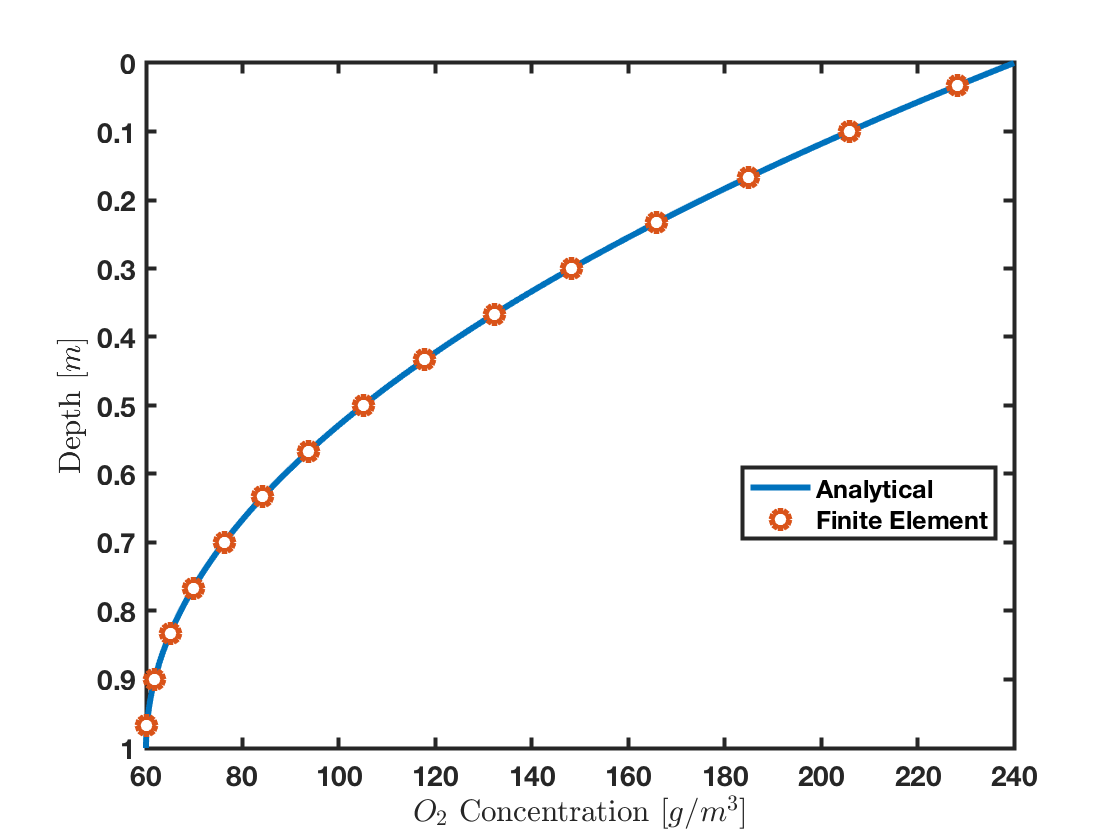

linewidth = 3 ;
fontsize = 14 ;
markersize = linewidth*3 ;

p1.LineWidth = linewidth ;

p2.LineWidth = linewidth ;
p2.LineStyle = 'none' ;
p2.Marker = 'o' ;
p2.MarkerFaceColor = 'auto' ;
p2.MarkerSize = markersize ;

ax1.YDir = 'reverse' ;
ax1.FontSize = fontsize ;
ax1.FontWeight = 'bold' ;
ax1.LineWidth = linewidth-1 ;
ax1.XLabel.Interpreter = 'latex' ;
ax1.YLabel.Interpreter = 'latex' ;

leg1.Location = 'best' ;

# **Functions**

## **Build Grid**

function [Grid] = build_grid(Grid)
% author: Logan M Schmidt
% date: 2018-09-10
% Description:
%   This function takes in minimal definition of the computational domain 
%   and grid and computes all pertinent information about the grid.
% Input:
%   Grid.xmin = left boundary of the domain
%   Grid.xmax = right bondary of the domain
%   Grid.Nx   = number of grid cells
%
% Output: (suggestions)
% Grid.Lx         = scalar length of the domain
% Grid.dx         = scalar cell width
% Grid.Nfx        = number of fluxes in x-direction
% Grid.xc         = Nx by 1 column vector of cell center locations
% Grid.xf         = Nfx by 1 column vector of cell face locations
% Grid.dof        = Nx by 1 column vector from 1 to N containig the degrees of freedom, i.e. cell numbers
% Grid.dof_xmin   = scalar cell degree of freedom corrsponding to the left boundary
% Grid.dof_xmax   = scalar cell degree of freedom corrsponding to the right boundary
% Grid.dof_f_xmin = scalar face degree of freedom corrsponding to the left boundary
% Grid.dof_f_xmax = scalar face degree of freedom corrsponding to the right boundary
% + anything else you might find useful
%
% Example call:
% >> Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 10;
% >> Grid = build_grid(Grid);

Grid.Lz         = Grid.zmax - Grid.zmin ;
Grid.dz         = Grid.Lz/Grid.Nz ;
Grid.Nfz        = Grid.Nz + 1 ;
Grid.zc         = linspace(Grid.zmin+Grid.dz/2,Grid.zmax-Grid.dz/2,Grid.Nz)' ; 
Grid.zf         = linspace(Grid.zmin,Grid.zmax,Grid.Nfz)' ;
Grid.dof        = linspace(1,Grid.Nz,Grid.Nz)' ;
Grid.dof_zmin   = Grid.dof(1) ;
Grid.dof_zmax   = Grid.dof(end) ;
Grid.dof_f_zmin = Grid.dof(1) ;
Grid.dof_f_zmax = Grid.dof(end) + 1 ;

Grid.N          = Grid.Nz ;
Grid.Nf         = Grid.Nfz ;
Grid.V          = Grid.dz^3*ones(Grid.Nz,1) ;
Grid.A          = Grid.dz^2*ones(Grid.Nfz,1) ;
end

## Build Operators

function [D,G,I]=build_ops(Grid)
% author: Logan M Schmidt
% date: 2018-09-10
% description:
%   This function computes the discrete divergence and gradient matrices on 
%   a regular staggered grid using central difference approximations. The
%   discrete gradient assumes homogeneous boundary conditions.
% Input:
%   Grid = structure containing all pertinent information about the grid.
% Output:
%   D = Nx by Nx+1 discrete divergence matrix
%   G = Nx+1 by Nx discrete gradient matrix
%   I = Nx by Nx identity matrix
%
% Example call:
% >> Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 10;
% >> Grid = build_grid(Grid);
% >> [D,G,I]=build_ops(Grid);

B = [-1*ones(Grid.Nz,1), ones(Grid.Nz,1)] ;
d = [0 1] ;
D = (1./Grid.dz)*spdiags(B,d,Grid.Nz,Grid.Nfz) ;
G = -D' ; G(1,1) = 0 ; G(end,end) = 0 ;
I = speye(Grid.Nz) ;
end

## Build Boundary

function [B,N,fn] = build_bnd(Param,Grid,I)
% author: Logan M Schmidt
% date: 2018-09-14
% Description:
% This function computes the operators and r.h.s vectors for both Dirichlet
% and Neumann boundary conditions.
%
% Input:
% Grid = structure containing all pertinent information about the grid.
% Param = structure containing all information about the physical problem
%         in particular this function needs the fields
%           Param.dof_dir = Nc by 1 column vector containing
%                           the dof's of the Dirichlet boundary.
%           Param.dof_neu = column vector containing
%                           the dof's of the Neumann boundary.
%           Param.qb = column vector of prescribed fluxes on Neuman bnd.
%           I = identity matrix in the full space
%
% Output:
% B = Nc by N matrix of the Dirichlet constraints
% N = (N-Nc) by (N-Nc) matrix of the nullspace of B
% fn = N by 1 r.h.s. vector of Neuman contributions
%
% Example call:
% >> Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 10;
% >> Grid = build_grid(Grid);
% >> [D,G,I]=build_ops(Grid);
% >> Param.dof_dir = Grid.dof_xmin;     % identify cells on Dirichlet bnd
% >> Param.dof_f_dir = Grid.dof_f_xmin; % identify faces on Dirichlet bnd
% >> Param.dof_neu = Grid.dof_xmax;     % identify cells on Neumann bnd
% >> Param.dof_f_neu = Grid.dof_f_xmax; % identify cells on Neumann bnd
% >> Param.qb = 1; % set bnd flux
% >> [B,N,fn] = build_bnd(Param,Grid,I);

B = I(Param.dof_dir,:) ;
N = I ; N(:,Param.dof_dir) = [] ;
switch nargout
    case 3    
        fn =  Param.Jb*Grid.A(Param.dof_neu)./Grid.V(Param.dof_neu)*...
            I(:,Param.dof_neu) ;
    otherwise
        fn = [] ;
end
end

## Solve Linear Boundary Value Problem

function [u] = solve_lbvp(L,fs,B,g,N)
% author: Logan M Schmidt
% date: 2018-09-14
% Description
% Computes the solution $u$ to the linear differential problem given by
%
% $$\mathcal{L}(u)=f \quad x\in \Omega $$
%
% with boundary conditions
%
% $$\mathcal{B}(u)=g \quad x\in\partial\Omega$$.
%
% Input:
% L = matrix representing the discretized linear operator of size N by N,
%       where N is the number of degrees of fredom
% f = column vector representing the discretized r.h.s. and contributions
%       due non-homogeneous Neumann BC's of size N by 1
% B = matrix representing the constraints arising from Dirichlet BC's of
%       size Nc by N
% g = column vector representing the non-homogeneous Dirichlet BC's of size
%       Nc by 1.
% N = matrix representing a orthonormal basis for the null-space of B and
%       of size N by (N-Nc).
% Output:
% u = column vector of the solution of size N by 1
%
% Example call:
% >> Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 10;
% >> Grid = build_grid(Grid);
% >> [D,G,I]=build_ops(Grid);
% >> Param.dof_dir = Grid.dof_xmin;       % identify cells on Dirichlet bnd
% >> Param.dof_f_dir = Grid.dof_f_xmin;   % identify faces on Dirichlet bnd
% >> Param.dof_neu = Grid.dof_xmax;       % identify cells on Neumann bnd
% >> Param.dof_f_neu = Grid.dof_f_xmax;   % identify cells on Neumann bnd
% >> Param.qb = 1;                        % set bnd flux
% >> Param.g = 0;                         % set bnd head
% >> [B,N,fn] = build_bnd(Param,Grid,I);  % Build constraint matrix and
%       the basis for its nullspace
% >> L = -D*G;                            % Laplacian operator
% >> fs = spalloc(Grid.N,1,0);            % r.h.s. (zero)
% >> u = solve_lbvp(L,fs+fn,B,Param.g,N); % Solve lbvp
% =========================================================================

% Get reduced system matrix by projecting into nullspace of B
Lr = N'*L*N ;

% FIND PARTICULAR SOLUTION ------------------------------------------------
upr = (B*B')\g ; % Solve for reduced particular solution
up  = B'*upr ;   % get full particular solution by projecting up

% FIND HOMOGENOUS SOLUTION ------------------------------------------------
% Compute additional r.h.s from heterogenous Dirichlet B.C.s
fd = -L*up ;
% Compute new total r.h.s. 
f = fs + fd ;
% Get reduced r.h.s. by projecting r.h.s into nullspace of B 
fr = N'*f ;      
% Solve for reduced homogenous solution
uor = Lr\fr ;   
% Get full homogenous solution by projecting up
uo = N*uor ;

% COMPUTE FULL SOLUTION ---------------------------------------------------
u = uo + up ;
end

## Compute Flux

function [q] = comp_flux(D,Ds,G,C,fs,Grid,Param)
% author: Logan Schmidt
% date: 2018-09-29
% Description:
% Computes the mass conservative fluxes across all boundaries from the
% residual of the compatability condition over the boundary cells.
% Note: Current implmentation works for all cases where one face
% is assigend to each bnd cell. So conrner cells must have
% natual BC?s on all but one face.
%
% Input:
% D     = N by Nf discrete divergence matrix.
% Kd    = Nf by Nf conductivity matrix.
% G     = Nf by N discrete gradient matrix.
% h     = N by 1 vector of flow potential in cell centers.
% fs    = N by 1 right hand side vector containing only source terms.
% Grid  = structure containing grid information.
% Param = structure contaning problem paramters and information about BC?s
%
% Output:
% q = Nf by 1 vector of fluxes across all cell faces,
%
% Example call:
% >> Grid.xmin = 0; Grid.xmax = 1; Grid.Nx = 10;
% >> Grid = build_grid(Grid);
% >> [D,G,I] = build_ops(Grid);
% >> L = -D*G; fs = ones(Grid.Nx,1);
% >> Param.dof_dir = Grid.dof_xmin;
% >> Param.dof_f_dir = Grid.dof_f_xmin;
% >> g = 0;
% >> Param.dof_neu = []; Param.dof_f_neu =[];
% >> [B,N,fn] = build_bnd(Param,Grid);
% >> h = solve_lbvp(L,fs+fn,B,g,N); 1
% >> q = comp_flux(D,1,G,h,fs,Grid,Param);

% Compute interior fluxes
q = -Ds*G*C ;
% Compute boundary fluxes
dof_cell    = [Grid.dof_zmin Grid.dof_zmax] ;
dof_face    = [Grid.dof_f_zmin Grid.dof_f_zmax] ;
sign        = [1; -1] ; 
q(dof_face) = sign.*(D(dof_cell,:)*q - fs(dof_cell))...
                .*(Grid.V(dof_cell)./Grid.A(dof_face)) ;
end